## Parte 3 - Speech Quantiation 

## Exercício 1.1

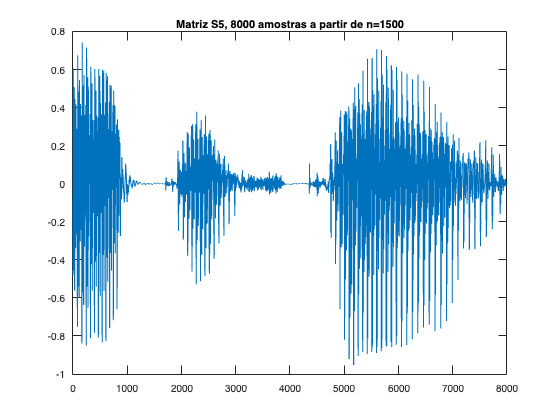

addpath("mcclellan/mcclellan/Functions/")
load("mcclellan/mcclellan/Data/s5.mat");

s5=s5./32768;

%soundsc(s5,8000,16);

vetor = s5(1500:9500-1);

plot(vetor);
title('Matriz S5, 8000 amostras a partir de n=1500')

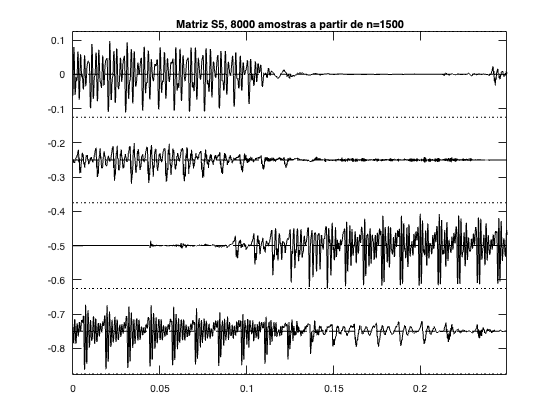

striplot(vetor,8000,2000);
title("Matriz S5, 8000 amostras a partir de n=1500");

## Exericio 1.2

maxS5 = max(vetor)

maxS5 = 0.7417

minS5 = min(vetor)

minS5 = -0.9521

avgS5 = mean(vetor)

avgS5 = 2.1649e-04

meanSqrS5 = meansqr(vetor)

meanSqrS5 = 0.0375

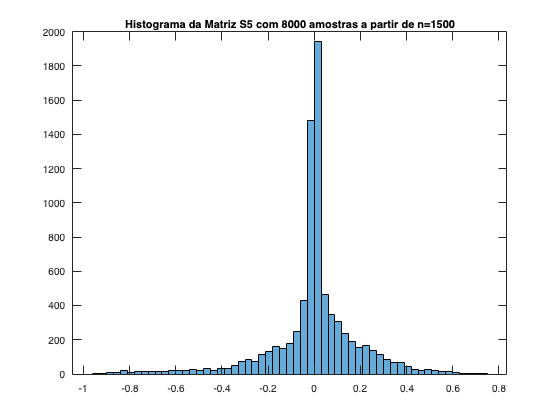

histogram(vetor)
 title("Histograma da Matriz S5 com 8000 amostras a partir de n=1500")

o resultado do histograma é consistente com o observado na forma de onda, posto que o sinal analisado é um sinal de audio, de caráter oscilatório, limitado em potência e em banda de frequência. 

## Exercício 1.3

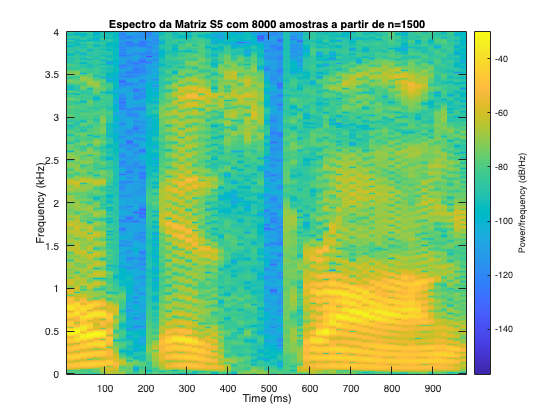

 janela = hamming(256);
 f=0:1:4000;
 spectrogram(vetor, janela,[],f,8000,'yaxis'); 
 title("Espectro da Matriz S5 com 8000 amostras a partir de n=1500")